%TODO: Could make an if loop for if sampling frequency, duration and other
%properties are the same, to just create one global var instead of loads.

[S,Fs] = audioread('Music library\5 second a new beginning.mp3');

[T1,Fs1] = audioread("Music library\Recorded\Original\creative minds.m4a");
[T2,Fs2] = audioread("Music library\Recorded\Original\a new beginning.m4a");
[T3,Fs3] = audioread("Music library\Recorded\Original\Cute.m4a");

%[T3,Fs3] = audioread("Music library\Cut down 30s\a new beginning cut.mp3");

%TODO: If two channels, run mean loop. 
%Create Matrix of all stats around here so one martrx/table can be
%refrenced throughout

S = mean(S,2);
T1 = mean(T1,2);
T2 = mean(T2,2);
T3 = mean(T3,2);

timeInSeconds = numel(S)/Fs;
timeInSeconds1 = numel(T1)/Fs1;
timeInSeconds2 = numel(T2)/Fs2;
timeInSeconds3 = numel(T3)/Fs3;


% plot(S(:,1))
% plot(T1(:,1))
% plot(T2(:,1))
numel(T1)

ans = 863290

numel(T2)

ans = 907087

numel(T3)

ans = 847913


[P1,Q1] = rat(Fs/Fs1);          % Rational fraction approximation
[P2,Q2] = rat(Fs/Fs2);          % Rational fraction approximation
[P3,Q3] = rat(Fs/Fs3);          % Rational fraction approximation

T1 = resample(T1,P1,Q1);        % Change sampling rate by rational factor
T2 = resample(T2,P2,Q2);        % Change sampling rate by rational factor
T3 = resample(T3,P3,Q3);        % Change sampling rate by rational factor

numel(T1)

ans = 793148

numel(T2)

ans = 833387

numel(T3)

ans = 779021

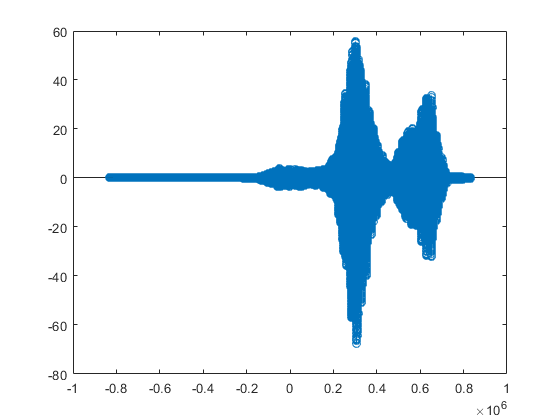




[C1,lag1] = xcorr(T1,S);        
[C2,lag2] = xcorr(T2,S);
[C3,lag3] = xcorr(T3,S);

% c1 = xcorr(T1,S,0, "none")
% c2 = xcorr(T2,S,0, "none")
% c3 = xcorr(T3,S,0, "none")

stem(lag2, C2);

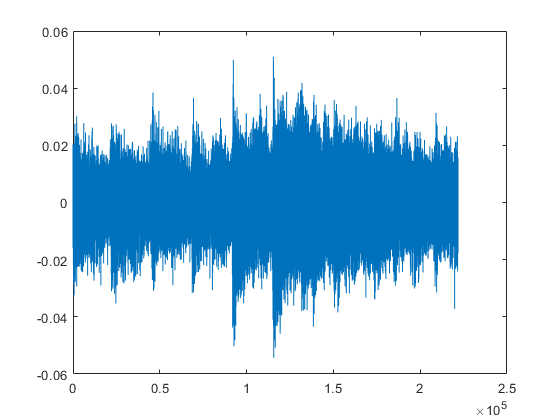


% newC2 = [C2, zeros(size(C2, 1), size(C1, 2)-size(C2, 2)); zeros(size(C1, 1)-size(C2, 1), size(C1, 2))];

newC2 = [C2, zeros(size(C2, 1), size(C3, 2)-size(C2, 2)); zeros(size(C3, 1)-size(C2, 1), size(C3, 2))];
newC1 = [C1, zeros(size(C1, 1), size(C3, 2)-size(C1, 2)); zeros(size(C3, 1)-size(C1, 1), size(C3, 2))];

% bigMatrixLol = [newC1 newC2 C3];
% maxCorr = max(bigMatrixLol);
% [largestCorrValue,columnOfLargest] = max(maxCorr);


% figure
% ax(1) = subplot(3,1,1); 
% plot(lag1/Fs,C1,'k')
% ylabel('Amplitude')
% grid on
% title('Cross-correlation between Template 1 and Signal')
% 
% ax(2) = subplot(3,1,2); 
% plot(lag2/Fs,C2,'r')
% ylabel('Amplitude') 
% grid on
% title('Cross-correlation between Template 2 and Signal')
% xlabel('Time(secs)') 
% 
% ax(3) = subplot(3,1,3); 
% plot(lag3/Fs,C3,'r')
% ylabel('Amplitude') 
% grid on
% title('Cross-correlation between Template 3 and Signal')
% xlabel('Time(secs)') 
% % 
% % ax(4) = subplot(5,1,4); 
% % plot(lag4/Fs,C4,'r')
% % ylabel('Amplitude') 
% % grid on
% % title('Cross-correlation between Template 4 and Signal')
% % xlabel('Time(secs)') 
% % 
% % ax(5) = subplot(5,1,5); 
% % plot(lag5/Fs,C5,'r')
% % ylabel('Amplitude') 
% % grid on
% % title('Cross-correlation between Template 5 and Signal')
% % xlabel('Time(secs)') 
% % 
% axis(ax(1:3),[-5 (timeInSeconds2) (min(C2)) (max(C2)) ])
% hold off

[~,I] = max(abs(C1));
SampleDiff1 = lag1(I);

[~,I] = max(abs(C2));
SampleDiff2 = lag2(I);

[~,I] = max(abs(C3));
SampleDiff3 = lag3(I);


poop = lag3';

elementsS = numel(S);
elementsT1 = numel(T1);
elementsT2 = numel(T2);
elementsT3 = numel(T3);

% if elementsS > elementsT1
%     diff = elementsS - elementsT1;
%     indexToDeleteFrom = elementsS - diff;
%     S(indexToDeleteFrom + 1:end,:) = [];
% elseif elementsR50 > elementsS
%     diff = elementsR50 - elementsS;
%     indexToDeleteFrom = elementsR50 - diff;
%     R50(indexToDeleteFrom:end,:) = [];
% end

closestMatchedT1 = T1(SampleDiff1:(numel(S) + SampleDiff1 -1));
closestMatchedT2 = T2(SampleDiff2:(numel(S) + SampleDiff2 -1));
closestMatchedT3 = T3(SampleDiff3:(numel(S) + SampleDiff3 -1));

%plot(closestMatchedT1)
plot(closestMatchedT2)

% plot(closestMatchedT2)
% plot(S)
% %plot(closestMatchedT3)


cc = corrcoef(S,closestMatchedT1);
similarityCoefficientT1 = cc(1,2)

similarityCoefficientT1 = -0.0323


cc = corrcoef(S,closestMatchedT2);
similarityCoefficientT2 = cc(1,2)

similarityCoefficientT2 = -0.2254


cc = corrcoef(S,closestMatchedT3);
similarityCoefficientT3 = cc(1,2)

similarityCoefficientT3 = 0.0301





timeDiff = SampleDiff2/Fs;

delay = finddelay(S,T2);

alignedSignals = alignsignals(S,T2);
% plot(alignedSignals)
% 
% plot(T2)
% plot(closestMatched)
